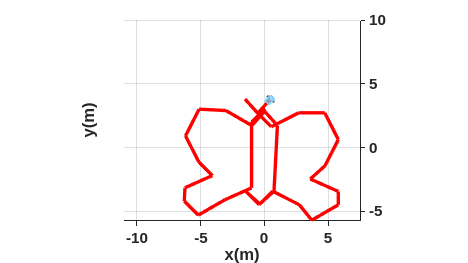

clear; close all; clc;

%%%%%%%%%%%%%%%%%%%%%%%%%%% CONFIGURACION INICIAL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ts = 0.1;
v_const = 0.5;           % Velocidad lineal constante
w_const = pi/6;          % Velocidad angular constante

waypoints = [
               0.05,  3.06;
              -1.00,  2.00;
              -1.00, -3.14;
              -3.06, -4.15;
              -5.13, -5.3;
              -6.17, -4.17;
              -6.17, -3.12;
              -4.10, -2.11;
              -5.13, -1.02;
              -6.18,  0.99;
              -5.14,  3.09;
              -3.07,  3.08;
              -1.00,  2.00;
               0.05,  3.06;
               1.08,  2.00;
               1.08, -3.14;
               0.035, -4.15;
              -1.00, -3.14;
               0.035, -4.15;
               1.08, -3.14;
               3.16, -4.15;
               4.14, -5.3;
               6.23, -4.17;
               6.23, -3.12;
               4.10, -2.11;
               5.20, -1.02;
               6.24,  0.99;
               5.20,  3.09;
               3.16,  3.10;
               1.08,  2.00;
               0.05,  3.06;
              -0.93,  4.13 
               0.05,  3.06;
               1.07, 4.13;
];


% Inicialización de estados
x = 0.05; y = 3.06; phi = 0;
x_traj = x; y_traj = y; phi_traj = phi;

%%%%%%%%%%%%%%%%%%%%%% GENERAR TRAYECTORIA EN LAZO ABIERTO %%%%%%%%%%%%%%%%%%%%

for i = 1:size(waypoints,1)-1
    dx = waypoints(i+1,1) - waypoints(i,1);
    dy = waypoints(i+1,2) - waypoints(i,2);
    
    ang_objetivo = atan2(dy, dx);
    dtheta = ang_objetivo - phi;
    
    t_giro = abs(dtheta) / w_const;
    pasos_giro = ceil(t_giro / ts);
    
    for k = 1:pasos_giro
        phi = phi + sign(dtheta) * w_const * ts;
        x_traj(end+1) = x;
        y_traj(end+1) = y;
        phi_traj(end+1) = phi;
    end
    
    dist = sqrt(dx^2 + dy^2);
    t_avance = dist / v_const;
    pasos_avance = ceil(t_avance / ts);
    
    for k = 1:pasos_avance
        x = x + v_const * cos(phi) * ts;
        y = y + v_const * sin(phi) * ts;
        x_traj(end+1) = x;
        y_traj(end+1) = y;
        phi_traj(end+1) = phi;
    end
end

N = length(x_traj);

%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuración de escena
scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([15 15]);
axis([-11 11 -8 10 0 2]);

% b) Cargar y graficar robot
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x_traj(1), y_traj(1), phi_traj(1), scale); hold on;

% c) Inicializar trayectoria
H2 = plot3(x_traj(1), y_traj(1), 0, 'r', 'LineWidth', 2);

% d) Animación del movimiento
for k = 1:N
    delete(H1); delete(H2);

xlim([-11.0 7.5])
ylim([-5.7 10.0])
zlim([0.00 2.00])
view([0.29 90.00])
    H1 = MobilePlot_4(x_traj(k), y_traj(k), phi_traj(k), scale);
    H2 = plot3(x_traj(1:k), y_traj(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end